# **Spatiotemporal patterns for movement preparation**

Author: Ambrosone Manuel

Purpose:

    1) Visualize mouse behaviour and cortical dynamics

    2) Extract and compare motion energy

    3) Analyze motifs and their relationship with movement

## **PATHS AND PARAMETERS**

%% PATHS AND PARAMETERS

clear; clc;

videoPath = fullfile(pwd, 'Mouse_video.mp4');
csvFile   = fullfile(pwd, 'DLC_file.csv');
dffFile   = fullfile(pwd, 'dff.mat');
motifsFile = fullfile(pwd, 'motifs.mat');

fps = 20;
frameRange = 1:200;

selectedROIs = {'Eye','Snout','Whisker','Right_Forepaw','Left_Forepaw'};
selected_motifs = [5, 12, 17];

% DLC-style colors for ROI
ROI_COLORS = struct( ...
    'Eye',        [0.49 0.18 0.56], ...
    'Snout',      [0.00 0.45 0.74], ...
    'Whisker',    [0.49 0.996 0.69], ...
    'Right_Forepaw',  [0.85 0.33 0.10], ...
    'Left_Forepaw',  [0.85 0.10 0.10]);

%% LOAD DATA

videoObj = VideoReader(videoPath);
load(dffFile,'dff');
load(motifsFile,'w','H','nanpxs');

## PREPROCESSING

%% COMPUTE MOTION ENERGY

% Behaviour
motionEnergy_behavior = CalculateMotionEnergyBehaviour(csvFile, selectedROIs);
motionEnergy_behavior = motionEnergy_behavior ./ max(motionEnergy_behavior(:));
motionEnergy_tot = sum(motionEnergy_behavior,1);
motionEnergy_tot = motionEnergy_tot ./ max(motionEnergy_tot);

% Cortex
motionEnergy_cortex = CalculateMotionEnergyCortical(dff);
motionEnergy_cortex = motionEnergy_cortex ./ max(motionEnergy_cortex);

% Motifs reconstruction
for i = 1:size(w,2)
    motifs(:,:,:,i) = conditionDffMat(squeeze(w(:,i,:))',nanpxs);
end

## SCHEMATIC OVERIEW

This figure shows a reference frame from the behavioral camera (left) and from the imaging camera (right).

Using DLC we tracked the position of different bodyparts: eye (purple), snout (blue), whisker (green), Right forepaw (orange) and Left forepaw( red).

Imaging was performed in mice injected with a virus (AAV-PHP.eb) carrying the flourescent protein GCaMP7f with the promotor  for excitatory neurons (CamKII).

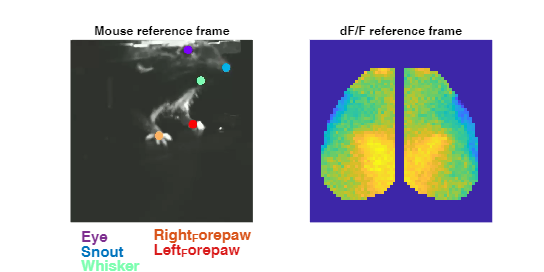

refFrame = read(videoObj, frameRange(1));
figure('Name','Mouse and dF/F schematic','Position',[100 100 1200 600]);

% ---------- MOUSE IMAGE ----------
subplot(1,2,1)
imshow(refFrame)
axis off
title('Mouse reference frame')

hold on
roiNames = fieldnames(ROI_COLORS);
nROIs = numel(roiNames);

nCols = 2;
nRows = ceil(nROIs/nCols); 
xStart = 30;                
xStep = 200;               
yStart = size(refFrame,1) + 40; 
yStep = 40;                 

for i = 1:nROIs
    col = ceil(i/nRows);              
    row = mod(i-1,nRows)+1;            
    roiName = roiNames{i};
    roiColor = ROI_COLORS.(roiName);
    text(xStart + (col-1)*xStep, yStart + (row-1)*yStep, roiName, ...
        'Color', roiColor, 'FontSize',12, 'FontWeight','bold')
end
hold off

% ---------- dF/F IMAGE ----------
subplot(1,2,2)
imagesc(dff(:,:,frameRange(1)))
colormap(parula)
axis image off
title('dF/F reference frame')
hold on

## INDIVIDUAL ROI TRACES FOR BEHAVIOR

This figure shows the motion energy for each ROI separately.

Each subplot corresponds to one ROI (eye, snout, whisker, R forepaw, L forepaw).

The traces are normalized, so you can compare relative activity across ROIs.

This is useful to see which body part is moving more at any given frame.

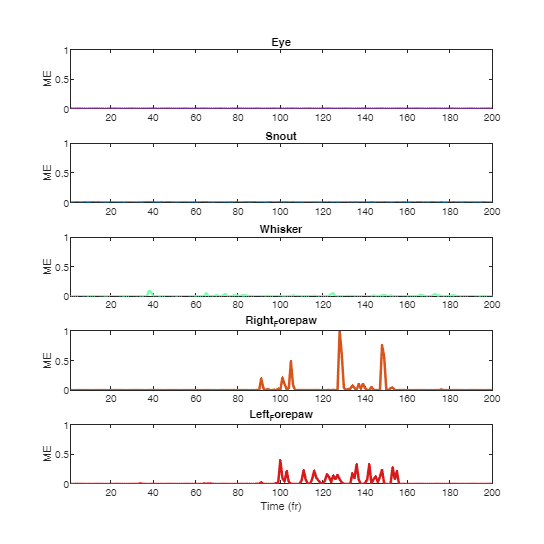

figure('Name','Behaviour Motion Energy per ROI','Position',[100 100 800 800]);

for r = 1:numel(selectedROIs)
    roiName = selectedROIs{r};
    roiColor = ROI_COLORS.(roiName);

    subplot(numel(selectedROIs),1,r)
    plot(motionEnergy_behavior(r,frameRange),'Color',roiColor,'LineWidth',2)
    ylim([0 1])
    xlim([1 numel(frameRange)])
    ylabel('ME')
    title(roiName)
end
xlabel('Time (fr)')

## COMPARISON BETWEEN dF/F AND CORTICAL MOTION ENERGY

This figure shows dF/F global and cortical motion energy in two stacked subplots.

While the dF/F changes when cortical areas are activated, motion energy increases when a different pattern of activation occurs (see what happen in the montage during 20 frames highligted in yellow).

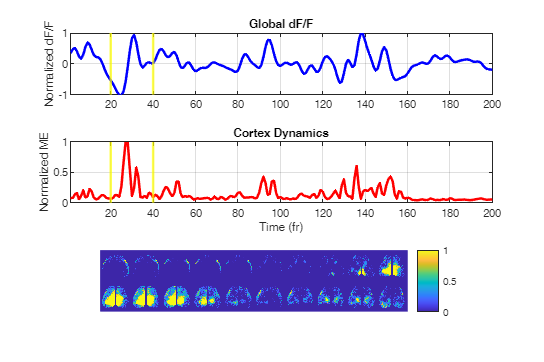

dff_global = squeeze(nanmean(nanmean(dff,1),2));
dff_global = dff_global ./ max(dff_global);

Tcompare = min([length(dff_global), length(motionEnergy_cortex)]);
framesComp = 1:Tcompare;

figure('Name','dF/F vs Cortical Motion Energy','Position',[100 100 900 600]);

% ---------- TOP: dF/F ----------
subplot(3,1,1)
plot(framesComp, dff_global(framesComp), 'b', 'LineWidth', 2)
xline(20,'y','LineWidth',2)
xline(40,'y','LineWidth',2)
ylim([-1 1])
xlim([1 numel(frameRange)])
ylabel('Normalized dF/F')
title('Global dF/F')
grid on

% ---------- MIDDLE: Cortical motion energy ----------
subplot(3,1,2)
plot(framesComp, motionEnergy_cortex(framesComp), 'r', 'LineWidth', 2)
xline(20,'y','LineWidth',2)
xline(40,'y','LineWidth',2)
ylim([0 1])
xlim([1 numel(frameRange)])
xlabel('Time (fr)')
ylabel('Normalized ME')
title('Cortex Dynamics')
grid on

% ---------- BOTTOM: Montage ----------
subplot(3,1,3)
montage(dff(:,:,20:40), [], "Size", [2 10])
colormap("parula")
colorbar

## INTERACTIVE FIGURES

Motion energy for each bodypart can be summed into a single value of Global movement. 

This figure shows the mouse video on top, the overall behaviour motion energy in the middle and the cortical motion energy at the bottom. The vertical line in the traces indicates the current frame of the video. This allows you to see how behaviour and cortical activity evolve frame by frame.

Wait for the end to interact with the video!

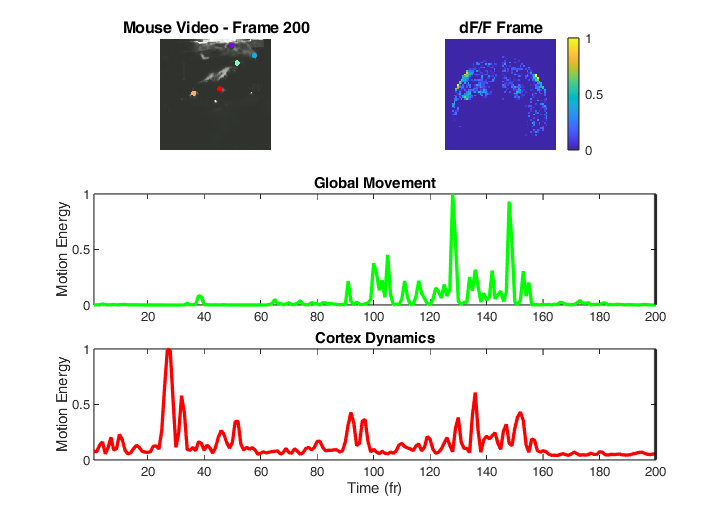

fig = figure('Name','Interactive Pipeline','Position',[400 400 1400 1000]);

for f = frameRange
    % --- MOUSE VIDEO ---
    subplot(3,2,1)
    imshow(read(videoObj,f))
    title(sprintf("Mouse Video - Frame %d",f))

    % --- dF/F VIDEO ---
    subplot(3,2,2)
    imagesc(dff(:,:,f))
    colormap(parula)
    axis image off
    title('dF/F Frame')
    colorbar
    caxis([0 1])

    % --- BEHAVIOUR ---
    subplot(3,2,[3 4])
    plot(motionEnergy_tot,'Color','g', 'LineWidth', 2)
    hold on
    xline(f,'k','LineWidth',2)
    hold off
    ylim([0 1])
    xlim([frameRange(1) frameRange(end)])
    ylabel('Motion Energy')
    title('Global Movement')

    % --- CORTEX ---
    subplot(3,2,[5 6])
    plot(motionEnergy_cortex,'Color','r', 'LineWidth', 2)
    hold on
    xline(f,'k','LineWidth',2)
    hold off
    ylim([0 1])
    xlim([frameRange(1) frameRange(end)])
    ylabel('Motion Energy')
    title('Cortex Dynamics')

    drawnow
end

xlabel('Time (fr)')

## VISUALIZE SOME MOTIFS

Each motif represents a recurring spatiotemporal activation pattern (MacDowell & Buschman., 2020).

Display example motifs as short sequences of frames. This provides an intuitive visualization of the spatial structure and temporal evolution of each motif.

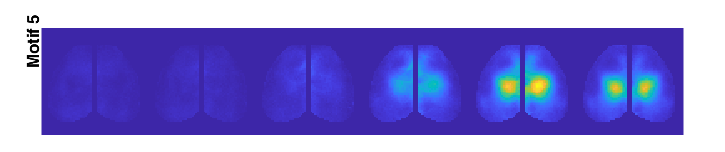

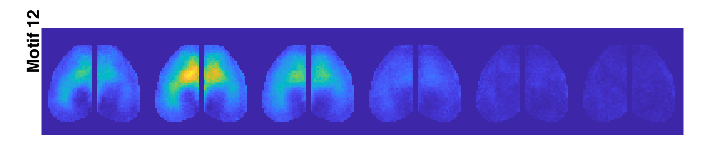

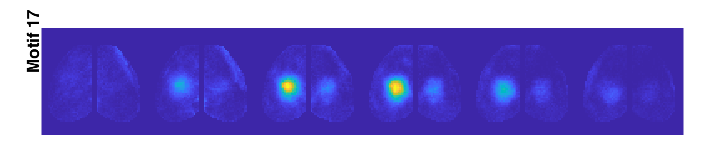

num_motifs = [5, 12, 17];

for i = 1:numel(num_motifs)

    j = num_motifs(i);  % indice reale del motif

    figure
    temp = motifs(:,:,7:12,j);

    montage(temp,"Size",[1 6])
    colormap parula
    clim auto
    text(-20, size(motifs,1)/2, ['Motif ' num2str(j)], ...
        'Rotation',90, ...
        'HorizontalAlignment','center', ...
        'FontWeight','bold')
    set(gca,'Position',get(gca,'Position') + [0 -0.1 0 0])

end

## MOTION ENERGY SOME EACH MOTIFS AND BEHAVIOR

Compute motion energy for each cortical motif as the frame-to-frame change in activity (squared difference). In parallel, compute global behavioral motion energy from tracked body parts. These signals will be used for comparison and correlation analysis.

This comparison highlights which motifs are active before movement epochs.

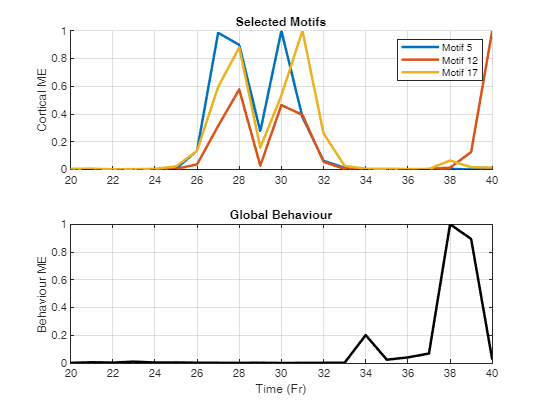

for j = 1:size(H,1)
        temp = tensor_convolve(w(:,j,:), H(j,:));
        cortical_activity = conditionDffMat(temp', nanpxs);
        [X, Y, T] = size(cortical_activity);
                
        for t = 1:T-1
            diff_frame = cortical_activity(:,:,t+1) - cortical_activity(:,:,t);
            motion_energy_cortical(t,j) = nansum(diff_frame(:).^2);
        end
end

motion_Energy_behavior = CalculateMotionEnergyBehaviour(csvFile, selectedROIs);
motionEnergy_tot = sum(motion_Energy_behavior,1);

selected_motifs = [5, 12, 17];
frameRange = 20:40;

figure('Name','Motion Energy Comparison','Position',[200 200 800 600]);

% ---------- CORTICAL (TOP) ----------
subplot(2,1,1)
hold on

for i = 1:numel(selected_motifs)
    j = selected_motifs(i);
    
    trace = motion_energy_cortical(frameRange, j);
    trace = trace / max(trace); % opzionale

    plot(frameRange, trace, 'LineWidth',2)
end

hold off
ylabel('Cortical ME')
xlim([frameRange(1) frameRange(end)])
title('Selected Motifs')
legend("Motif " + string(selected_motifs))
grid on

% ---------- BEHAVIOUR (BOTTOM) ----------
subplot(2,1,2)

beh = motionEnergy_tot(frameRange);
beh = beh / max(beh);

plot(frameRange, beh, 'k', 'LineWidth',2)

ylabel('Behaviour ME')
xlabel('Time (Fr)')
xlim([frameRange(1) frameRange(end)])
title('Global Behaviour')
grid on

## CROSS-CORRELATION BETWEEN MOTIFS AND MOVEMENTS

Compute cross-correlation between each motif's motion energy and global behavioral motion energy.

Only negative lags are considered to test whether cortical activity precedes movement. Higher values indicate stronger coupling between motif dynamics and movement. Peaks at negative lags suggest motifs that precede behavior.

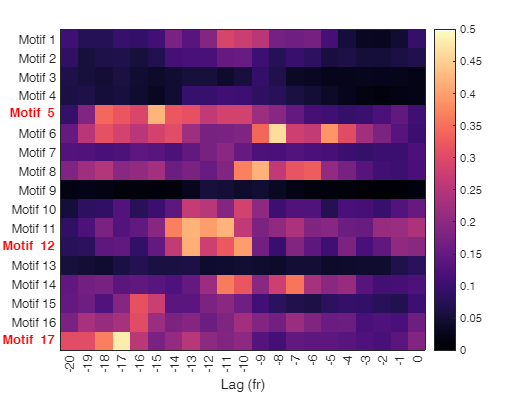

num_motifs = 17;
selected_motifs = [5, 12, 17];

specific_lags = -20:0;
num_lags = length(specific_lags);

cross_corr_matrix = nan(num_motifs, num_lags);

for motif = 1:num_motifs

    [cross_corr, lags] = xcorr(motion_energy_cortical(:, motif), ...
                               motionEnergy_tot(:), 45, 'coeff');

    for lag_idx = 1:num_lags
        lag_value = specific_lags(lag_idx);
        match_idx = find(lags == lag_value, 1);

        if ~isempty(match_idx)
            cross_corr_matrix(motif, lag_idx) = cross_corr(match_idx);
        end
    end
end

% ---------- PLOT ----------
figure;
imagesc(cross_corr_matrix, [0, 0.5]);
colormap("magma");
colorbar;

xlabel('Lag (fr)')

yticks(1:num_motifs)
yticklabels(arrayfun(@(i) ['Motif ' num2str(i)], 1:num_motifs, 'UniformOutput', false))

xticks(1:num_lags)
xticklabels(specific_lags)
xtickangle(90)

set(gca, 'TickLength',[0 0], 'Box','on')

% ---------- HIGHLIGHT SELECTED ----------
ax = gca;
labels = arrayfun(@(i) ['Motif ' num2str(i)], 1:num_motifs, 'UniformOutput', false);

for i = selected_motifs
    labels{i} = ['\bf\color{red}' labels{i}];
end

yticklabels(labels)